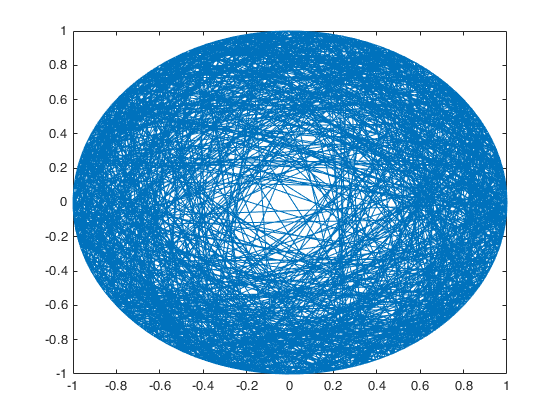

clear
%Código para dibujar la circunferencia y dibujar sobre ella las iteraciones
ang = linspace(0,2*pi) ;
plot(cos(ang),sin(ang))
hold on
%Contador para evaluar si el punto está en la circunferencia
i=0 ;
%Contador para evaluar si la longitud de la cuerda es mayor que raíz de 3
j=0 ;
%Bucle para simular las 1000 cuerdas
while i < 1000
    %Selección aleatoria uniforme de un punto (x,y)
    a = 2*rand(1, 1)-1 ;
    b = 2*rand(1, 1)-1 ;
    %Condicional para determinar si el punto generado está en el interior de la circunferencia
    if (a^2)+(b^2) <= 1
        %Cuerda generada entre la solución del sistema de ecuaciones presentado anteriormente
        line([((a^3) + a*(b^2) - sqrt(-(b^2)*((a^4) + (b^2)*(-1 + (b^2)) + (a^2)*(-1 + 2*(b^2)))))/((a^2) + ...
            (b^2)),((a^3) + a*(b^2) + sqrt(-(b^2)*((a^4) + (b^2)*(-1 + (b^2)) + (a^2)*(-1 + 2*(b^2)))))/((a^2) + ...
            (b^2))],[((a^2)*(b^2) + (b^4) + a*sqrt(-(b^2)*(-(a^2) + (a^4) - (b^2) + 2*(a^2)*(b^2) + (b^4))))/((a^2)*b + ...
            (b^3)),((a^2)*(b^2) + (b^4) - a*sqrt(-(b^2)*(-(a^2) + (a^4) - (b^2) + 2*(a^2)*(b^2) + (b^4))))/((a^2)*b + (b^3))])
        %Aumento del contador
        i = i + 1 ;
        %Condicional para determinar si la longitud de la cuerda generada es mayor que raíz de 3
        if sqrt((((a^3) + a*(b^2) - sqrt(-(b^2)*((a^4) + (b^2)*(-1 + (b^2)) + (a^2)*(-1 + 2*(b^2)))))/((a^2) + (b^2))-((a^3) + a*(b^2) + sqrt(-(b^2)*((a^4) + (b^2)*(-1 + (b^2)) + (a^2)*(-1 + 2*(b^2)))))/((a^2) + (b^2)))^2+(((a^2)*(b^2) + (b^4) + a*sqrt(-(b^2)*(-(a^2) + (a^4) - (b^2) + 2*(a^2)*(b^2) + (b^4))))/((a^2)*b + (b^3))-((a^2)*(b^2) + (b^4) - a*sqrt(-(b^2)*(-(a^2) + (a^4) - (b^2) + 2*(a^2)*(b^2) + (b^4))))/((a^2)*b + (b^3)))^2) > sqrt(3) 
            %Aumento del contador
            j = j + 1 ;
        end
    end
end

%Cantidad de cuerdas con longitud mayor que raíz de 3
j

j = 249

%Porcentaje de j
j/i

ans = 0.2490